# Simulación de Sistemas Eléctricos

# Actividad 7: Modelo de predicción 

- **Energía en t=t0 --->[]---> Energía en t=to+dt**

- **Variable independiente (x): Energía en t=t0 (Valor actual)**

- **Variable dependiente (f(x)): Energía en t=to+dt (Valor siguiente); dt=1seg**

- **Frecuencia de muestreo de los datos: 1 muestra por segundo (sps)**

- **Venta temporal de predicción: (dt=1día)**

Nombres:

- Estudiante 1: VA

- Estudiante 2: VA

Contenido:

- Descargar datos (.csv) desde desde repositorio (DataPort)

- **Paper: **[https://doi.org/10.1016/j.procs.2022.07.035](https://doi.org/10.1016/j.procs.2022.07.035)

- **Dataset:** [https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset)

- **Codigo Matlab:** [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- **Funciones de Matlab:** [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- **1.- Leer el archivo .csv usando Matlab y graficar los datos**

- **2.- Adecuador el dataset con la var. independiente (x) y la var. dependiente f(x)**

- **3.- Cambiar la frecuencia de muestreo de los datos (1 muestra por dia)**

- **4.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

- **5.- Seleccionar el modelo que tiene un menor error de predicción**

- **6.- Crear la función del mejor modelo**

- **Nota:** realizar cualquier cambio que usted considere adecuado

- **Despues:**

-     Utilizar más variables independientes 

-     Cambiar la ventana temporal de predicción (**dt > 1seg**)

#### **Eliminar datos de memoria y command window**

clear; %Borrar el korspace
clc; %Borrar el command window

#### Configuración de carpeta /src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

**Configuranción de carpeta de /data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');
filenames=FindCSV(datapath);

# **1.- Leer el archivo .csv usando Matlab y graficar los datos**

%Esto es lo que se hace con datos .csv
data=readtable(fullfile(datapath,filenames(1).name));
%clear dataRaw; %Borrar de memoria la variable que no usare despues
%Seleccionar las variables electricas de interes
data2=table2array(data(:,1:6)); % Convertir datos de string a float o int
data2(isnan(data2))=0; % Eliminar los datos NaN


#### Graficar todas las Variables

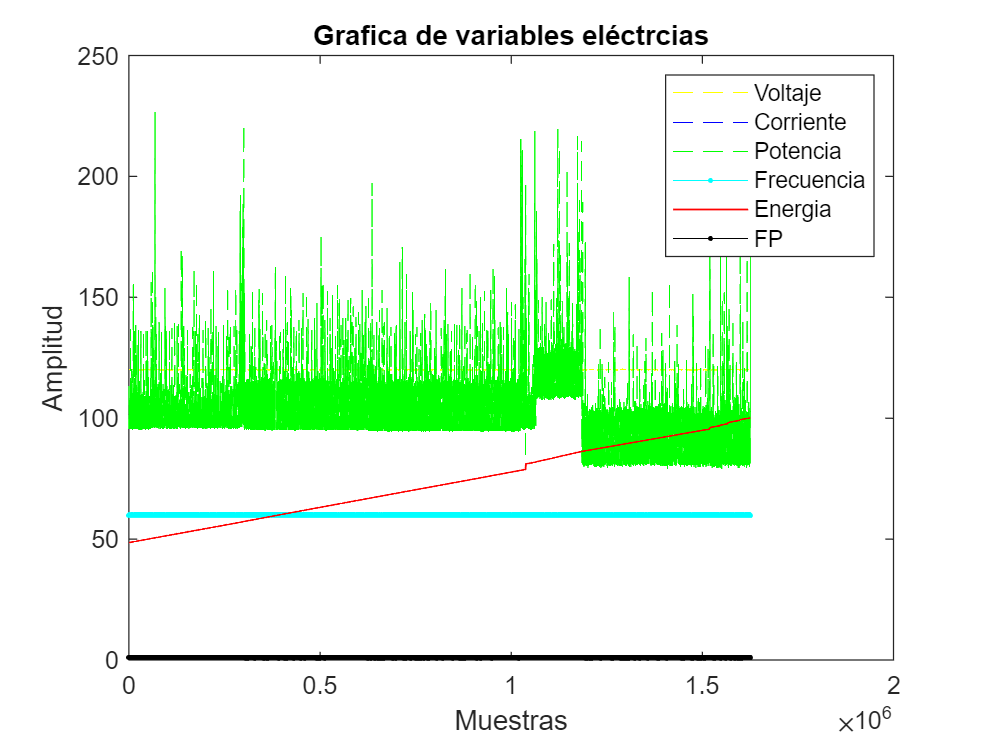

Voltaje=data2(:,1);
Corriente=data2(:,2);
Potencia=data2(:,3);
Frecuencia=data2(:,4);
Energia=data2(:,5);
FP=data2(:,6);

figure %crear una nueva grafica
%plot(data2) %plotea la grafica 1
plot(Voltaje,'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(Corriente,'b--',LineWidth=0.1);
plot(Potencia,'g--',LineWidth=0.01);
plot(Frecuencia,'c.-',LineWidth=0.1);
plot(Energia,'r',LineWidth=0.7);
plot(FP,'k.-',LineWidth=0.1);
hold off


title('Grafica de variables eléctrcias');
xlabel('Muestras');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

%Limpiar del workspace variables no utilizadas
clear FP; clear Potencia; clear Frecuencia; clear Corriente;clear Voltaje;
clear data;clear data2; clear datapath;

# **2.- Adecuador el dataset con la var. independiente (x) y la var. dependiente f(x)**

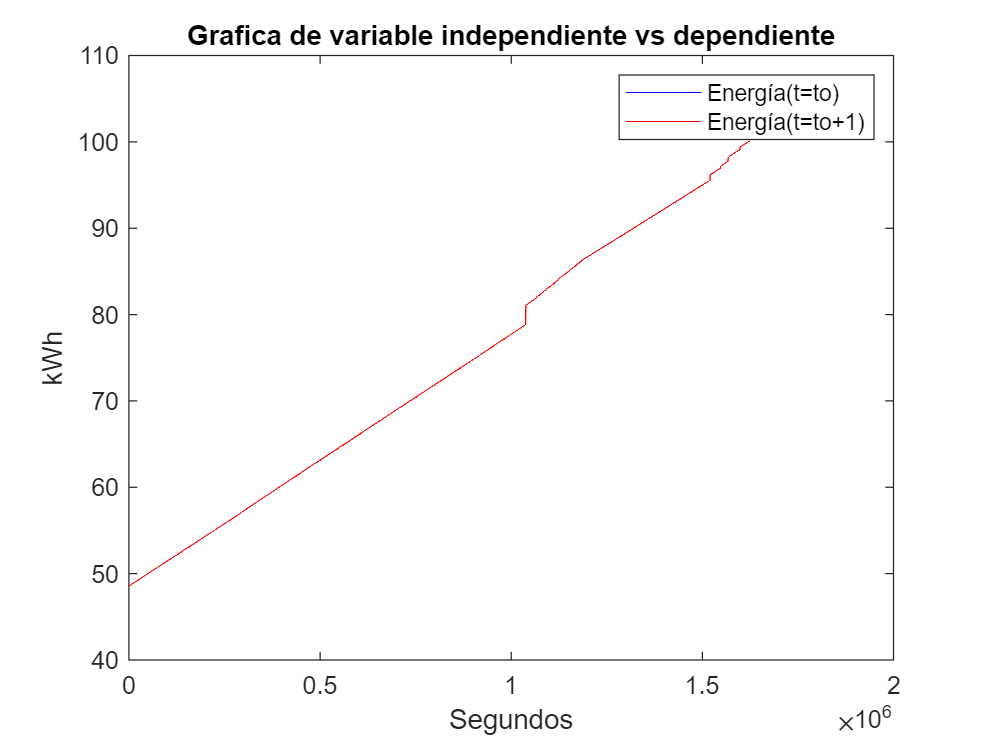

input=Energia(1:size(Energia,1)-1,1);% Variable independiente (x)
output=Energia(2:size(Energia,1),1);% Variable dependient f(x)

%Primeras columnas son las entradas o varianles independientes
%La ultima columna es la salida o variable dependiente
dataset=[input output];

 figure %crear una nueva grafica
 plot(input(:,1),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(output(:,1),'r',LineWidth=0.1);
 hold off
% 
 title('Grafica de variable independiente vs dependiente');
 xlabel('Segundos');
 ylabel('kWh');
 legend('Energía(t=to)','Energía(t=to+1)');

# **3.- Cambiar la frecuencia de muestreo de los datos (1 muestra por dia)**

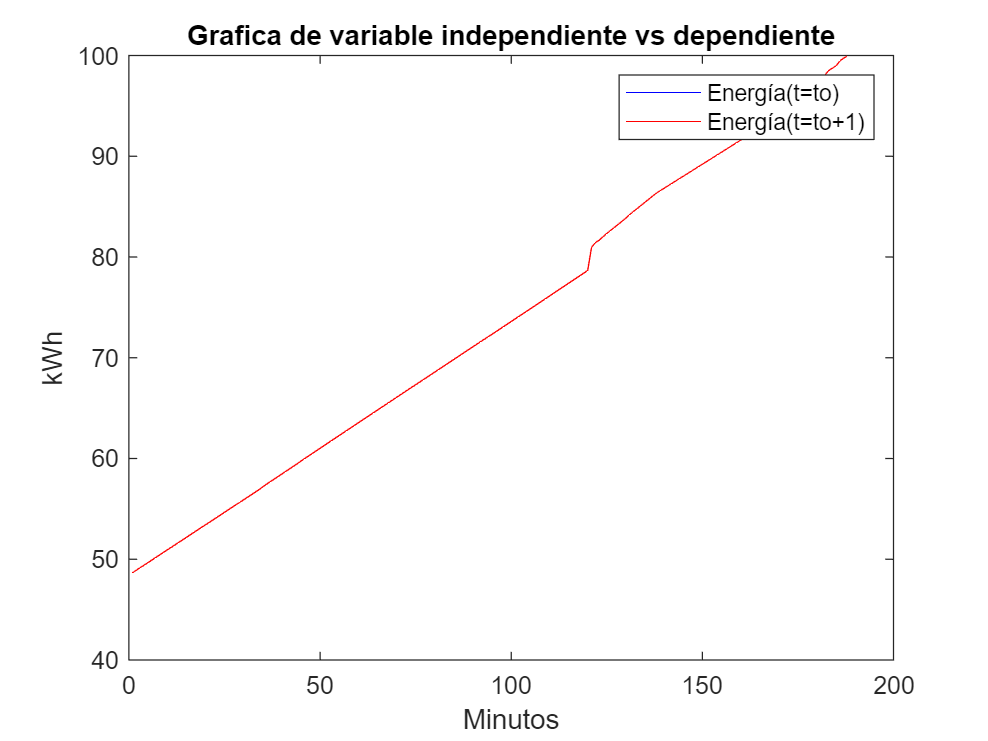

win=360*24; %dado a que los datos estan en segundos y queremos llevarlo a dias
datasetMean=fData_MeanWin(dataset,win);%60 segundos 

%70 de entrenamiento y 30% de vtesting
Training=datasetMean(1:round(size(datasetMean,1)*0.7),:);% fila 1 hasta la fila del 70% de todas las filas
%desde la fila del 70% de todas las filas hasta la ultima fila
Testing=datasetMean(round(size(datasetMean,1)*0.7)+1:round(size(datasetMean,1)),:);

 figure %crear una nueva grafica
 plot(datasetMean(:,1),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(datasetMean(:,2),'r',LineWidth=0.1);
 hold off
% 
 title('Grafica de variable independiente vs dependiente');
 xlabel('Dias');
 ylabel('kWh');
 legend('Energía(t=to)','Energía(t=to+1)');

# **4.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

regressionLearner

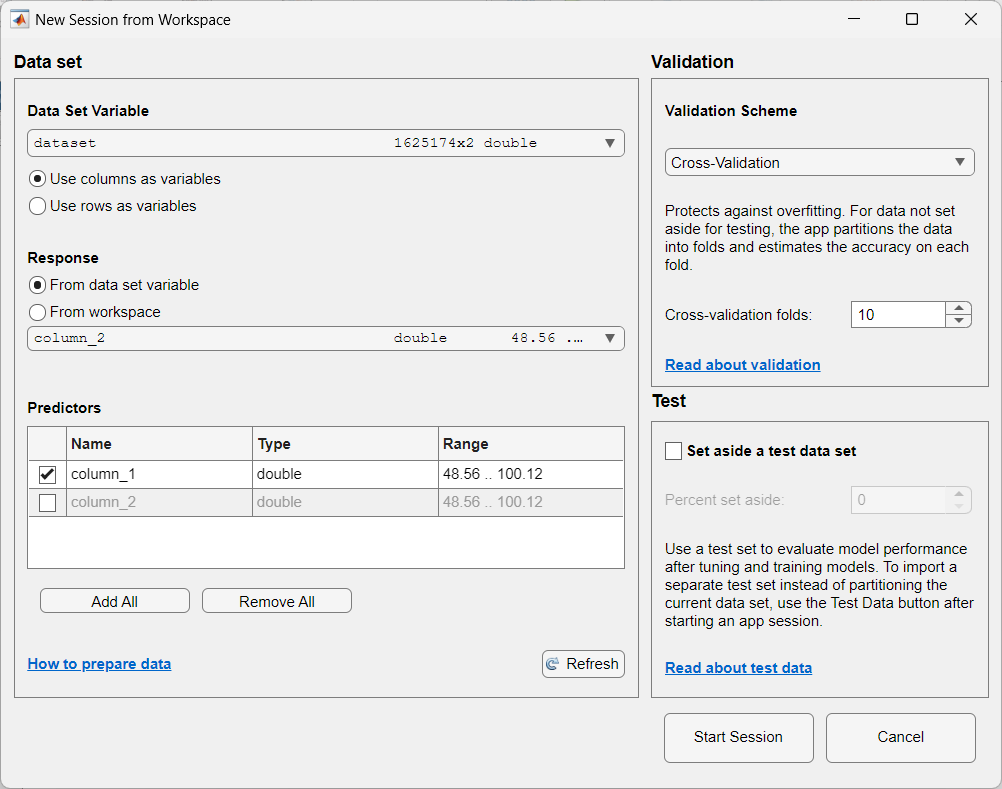

# **5.- Seleccionar el modelo que tiene un menor error de predicción**

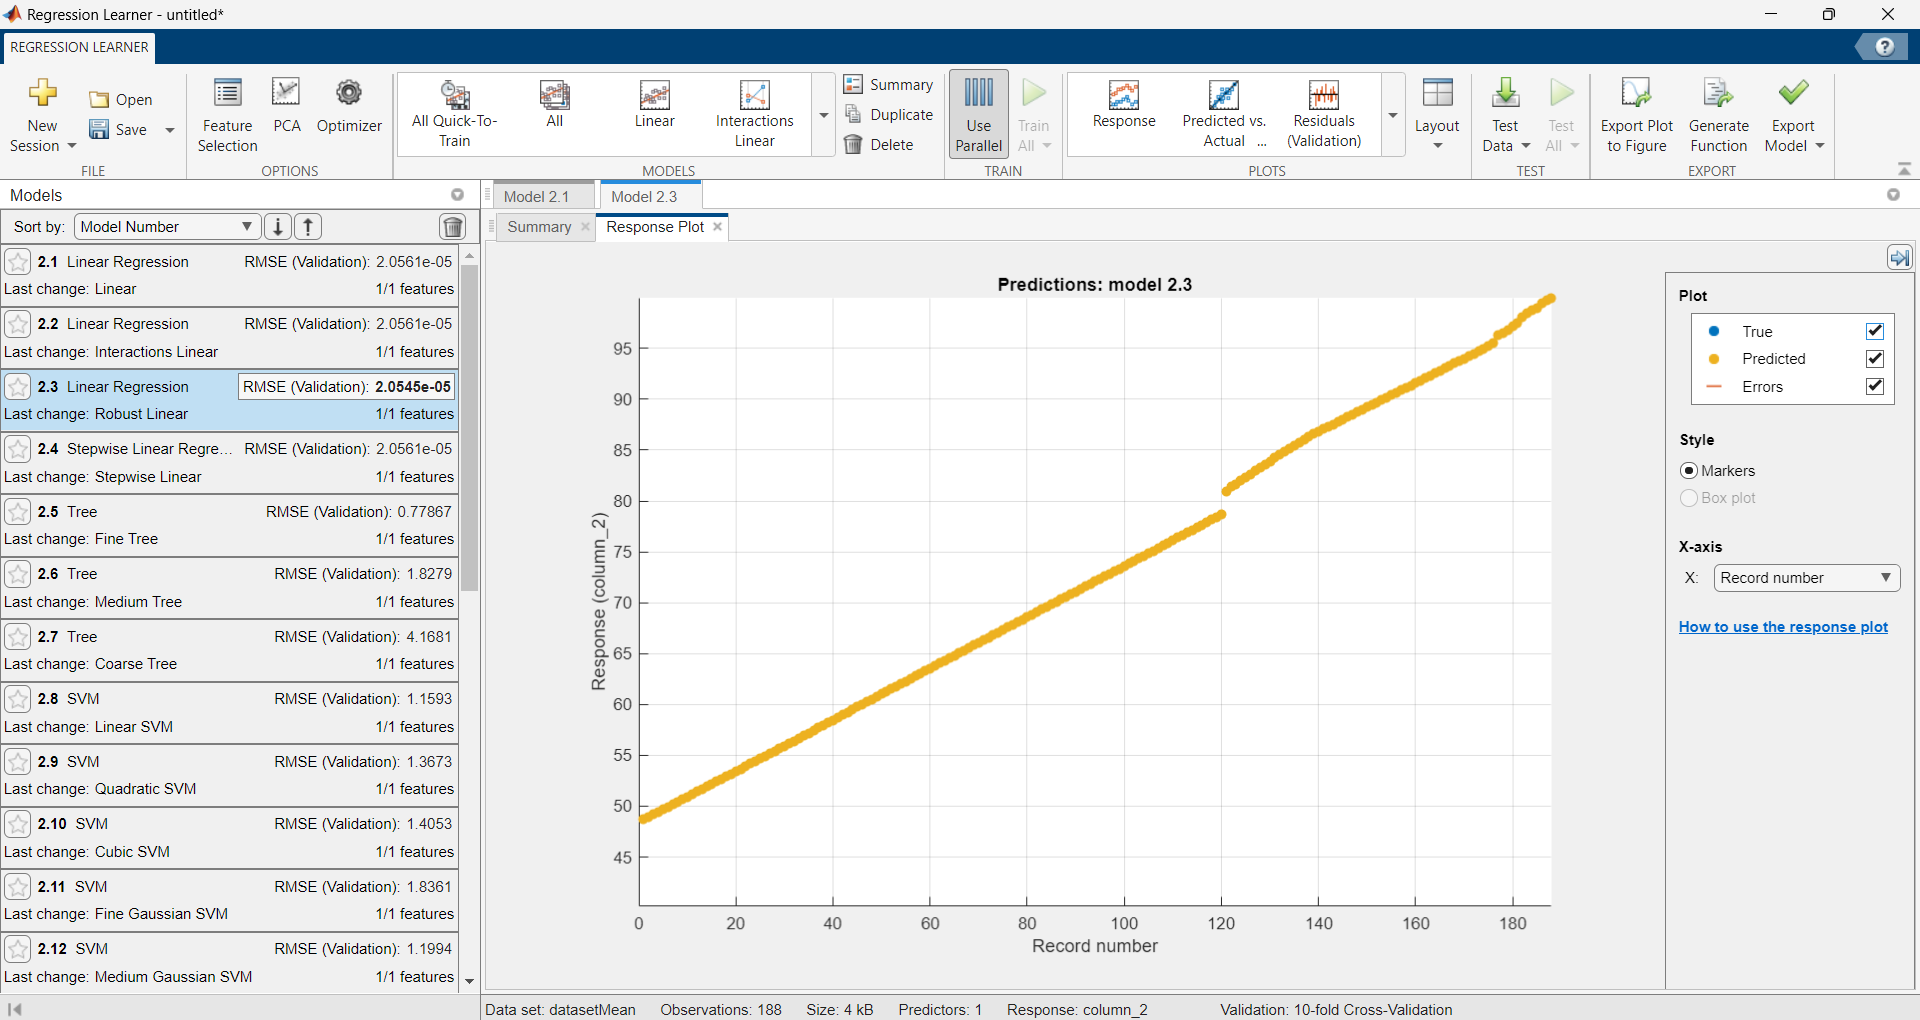

# **6.- Crear la función del mejor modelo **

[trainedModel, validationRMSE] = trainRegressionModel(Training)

trainedModel = struct with fields:
      predictFcn: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
     LinearModel: [1×1 LinearModel]
           About: 'This struct is a trained model exported from Regression Learner R2022a.'
    HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 1 columns because this model was trained using 1 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 2.2664e-05

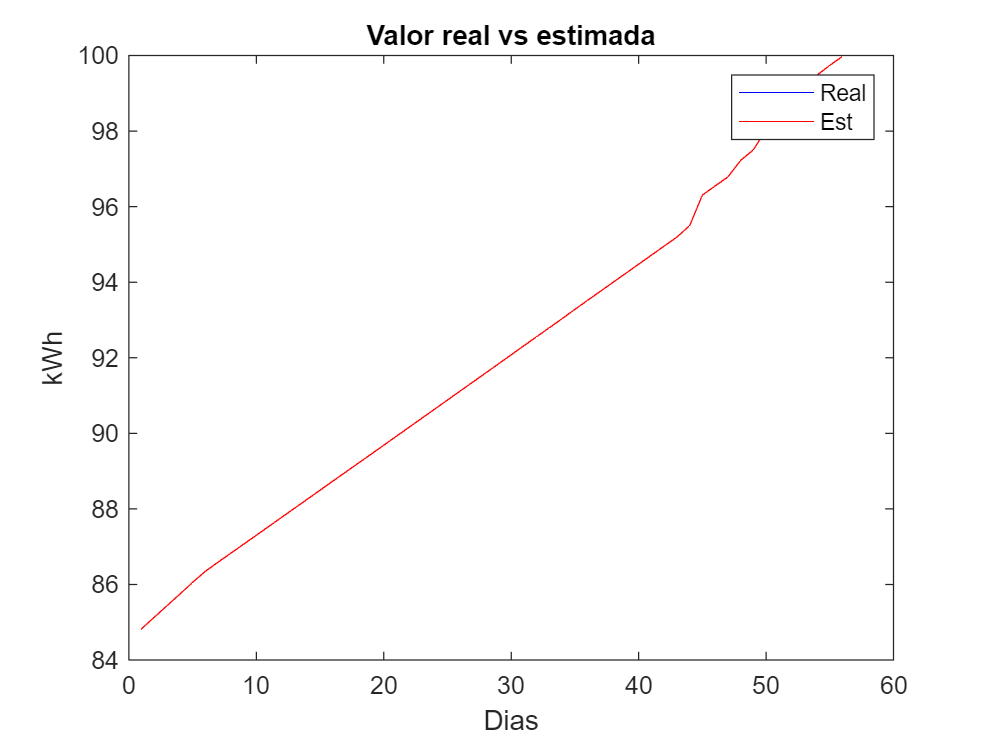

EnergiaEst=trainedModel.predictFcn(Testing(:,1));

 figure %crear una nueva grafica
 plot(Testing(:,2),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(EnergiaEst,'r',LineWidth=0.1);
 hold off
% 
 title('Valor real vs estimada');
 xlabel('Dias');
 ylabel('kWh');
 legend('Real','Est');